# Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles

In this script, we've implemented machine learning based Lithium-Ion battery capacity estimation using multi-Channel charging Profiles. Dataset used in this example is from "Battery data set" from NASA.

### Multi-Channel charging profiles of V, I, T data

To observe if charging profiles shows battery aging, we need to explore Voltage(V), Current(I) and Temperature(T) path through battery aging.

In below figure, we can observe that there are significant changes in charging profiles of V, I and T as a battery ages.

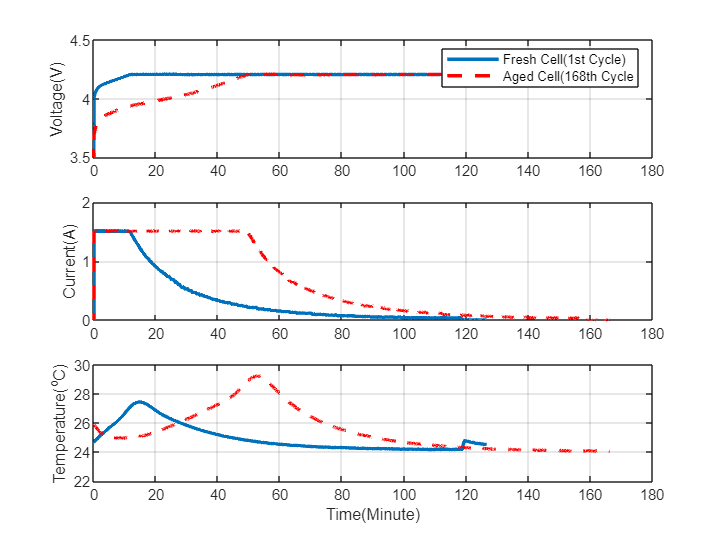

clear;
load B0005.mat
FTime = B0005.cycle(1).data.Time/60;
FreshCell_V = B0005.cycle(1).data.Voltage_measured;
FreshCell_I = B0005.cycle(1).data.Current_measured;
FreshCell_T = B0005.cycle(1).data.Temperature_measured;

ATime = B0005.cycle(168).data.Time/60;
AgedCell_V = B0005.cycle(168).data.Voltage_measured;
AgedCell_I = B0005.cycle(168).data.Current_measured;
AgedCell_T = B0005.cycle(168).data.Temperature_measured;

figure(1)
subplot(311)
plot(FTime, FreshCell_V, 'linewidth', 2), hold on, plot(ATime, AgedCell_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(1st Cycle)', 'Aged Cell(168th Cycle'), ylabel('Voltage(V)')
ylim([3.5 4.5]), grid on
subplot(312)
plot(FTime, FreshCell_I, 'linewidth', 2), hold on, plot(ATime, AgedCell_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), ylim([0 2]), grid on
subplot(313)
plot(FTime, FreshCell_T, 'linewidth', 2), hold on, plot(ATime, AgedCell_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), ylim([22 30]), grid on, xlabel Time(Minute)

Eventually, we observe the degradation characteristics per cycle as below figure.

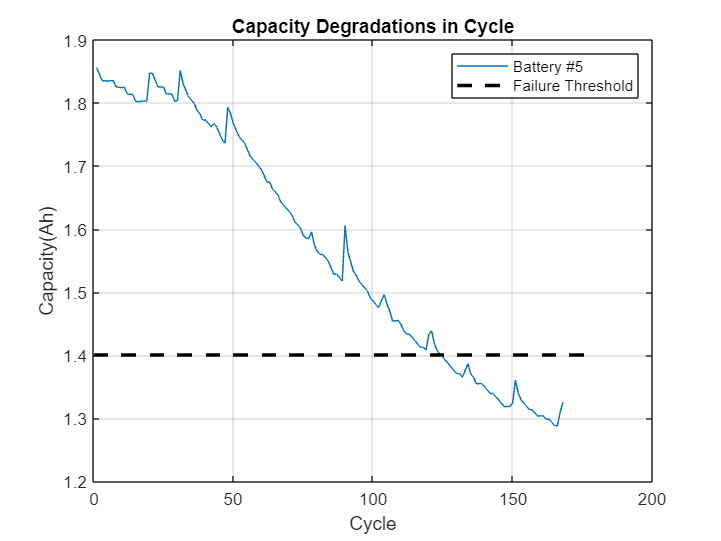

cap = extract_discharge(B0005);
figure
plot(cap), hold on
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Failure Threshold')
title('Capacity Degradations in Cycle')

### Data Preprocessing

Get ready for the training. The inputs of the proposed models in are the extracted features, which are obtained by the uniform sampling of the raw battery data. Specifically, they configure the input matrix as 30-dimensional vectors by concatenating the V, I, T charging profiles, each with 10 samples. The number of samples is chosen to consider the distinct changes in time and the model complexity. In addition, we average the data over sampling interval to prevent oscillation in short time interval.

charInput = extract_charge_preprocessing(B0005);

Initial capacity for each battery data is provided as belows in the dataset:

InitC = 1.86;

For better training since it retains the original distribution of data except for a scaling factor and transforms all the data into the range of [0,1]:

[xB, yB, ym, yr] = minmax_norm(charInput, InitC, cap);
Train_Input = xB;
Train_Output = yB; 

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

networkNeeded = feedforwardnet(10);
networkNeeded.trainParam.epochs = 100;
[networkNeeded, tr] = train(networkNeeded, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
There is not an open parallel pool.


layerCNN1 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.52 |         0.50 |       0.1359 |       0.1269 |          0.0010 |
|      25 |          50 |       00:00:11 |         0.24 |         0.24 |       0.0278 |       0.0298 |          0.0010 |
|      50 |         100 |       00:00:13 |         0.13 |         0.19 |       0.0085 |       0.0188 |          0.0010 |
|      75 |         150 |       00:00:15 |         0.07 |         0.15 |       0.0026 |   

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.63 |         0.56 |       0.1956 |       0.1582 |          0.0010 |
|      25 |          50 |       00:00:11 |         0.16 |         0.18 |       0.0124 |       0.0166 |          0.0010 |
|      50 |         100 |       00:00:12 |         0.07 |         0.13 |       0.0023 |       0.0082 |          0.0010 |
|      75 |         150 |       00:00:14 |         0.04 |         0.12 |       0.0008 |   

### Prediciton using each trained model

Make a prediction using trained models

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, 30, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

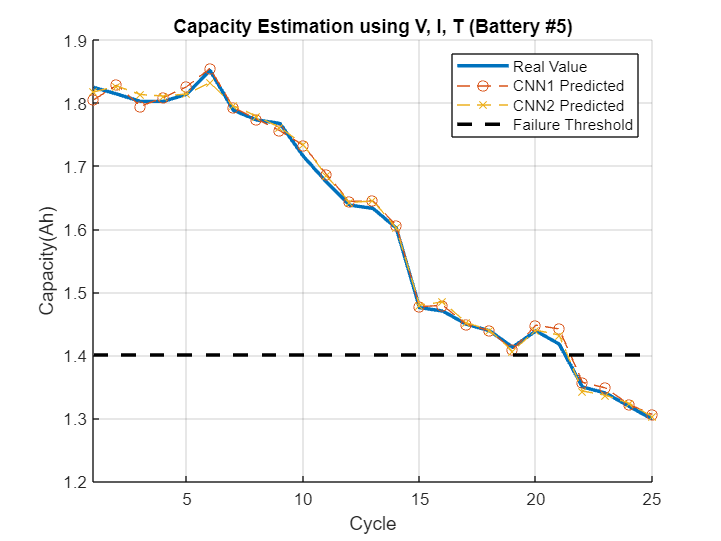

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pCNN1, 'o--'), plot(pCNN2, 'x--')
plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
title(['Capacity Estimation using V, I, T'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'CNN1 Predicted', 'CNN2 Predicted', 'Failure Threshold')